srcDir = "..\srcImages\";

barbara = readraw(srcDir + "barbara.raw");

    "→Retrieving Image "    "..\srcImages\barbara.raw"    " ..."



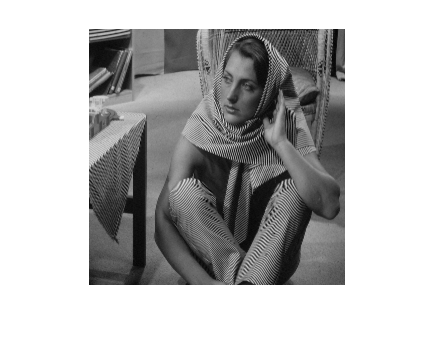

imshow(barbara);

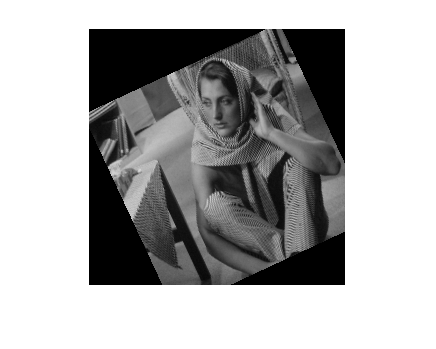


affectedBarbara = applyGeometryEffect(barbara, 3, 5, 2, 5);
imshow(affectedBarbara);

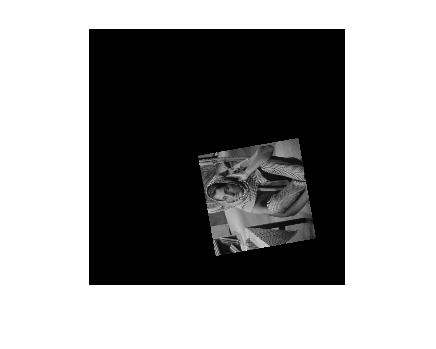


affectedBarbara = applyGeometryEffect(barbara, 3, 5, 2, 20);
imshow(affectedBarbara);

baboon = readraw(srcDir + "baboon.raw");

    "→Retrieving Image "    "..\srcImages\baboon.raw"    " ..."



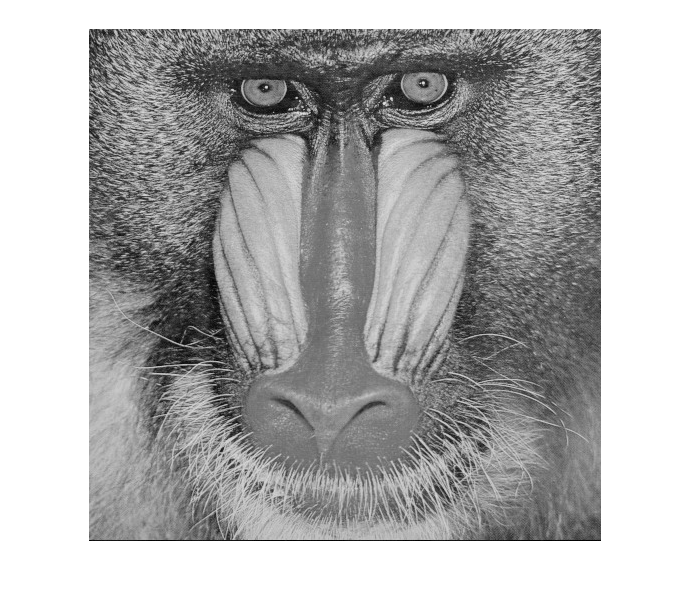

imshow(baboon);

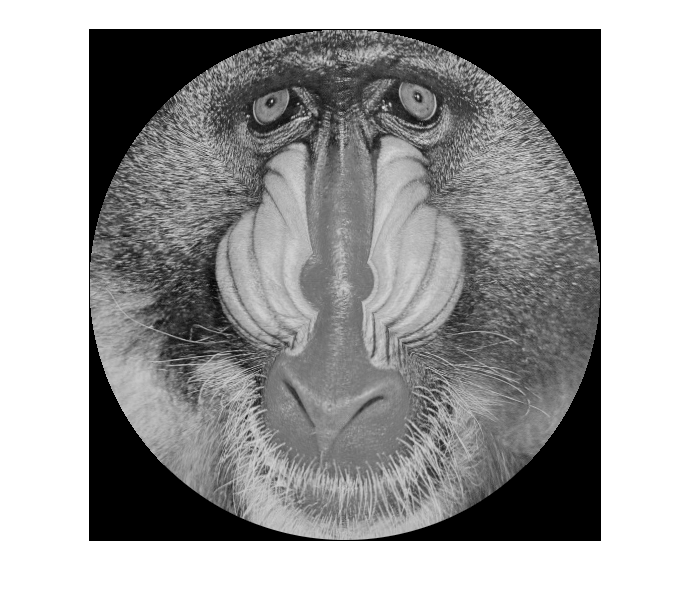


diskBaboon = toDisk(baboon);
imshow(diskBaboon);

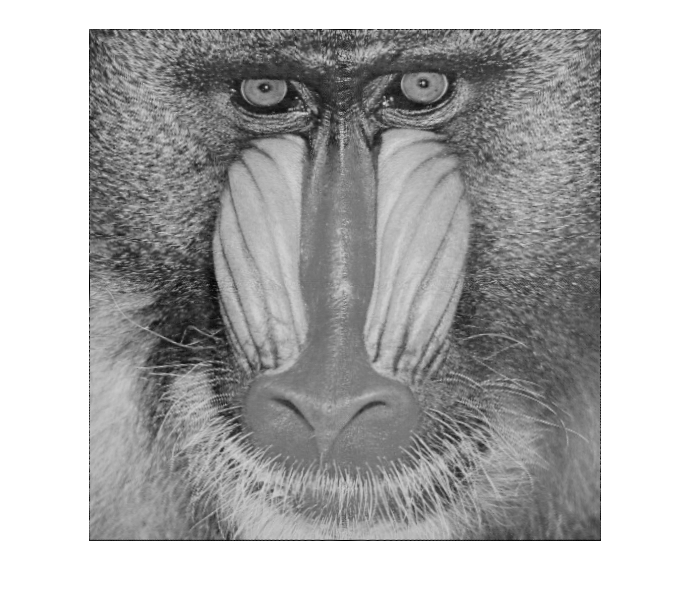


resquaredBaboon = fromDisk(diskBaboon);
imshow(resquaredBaboon);

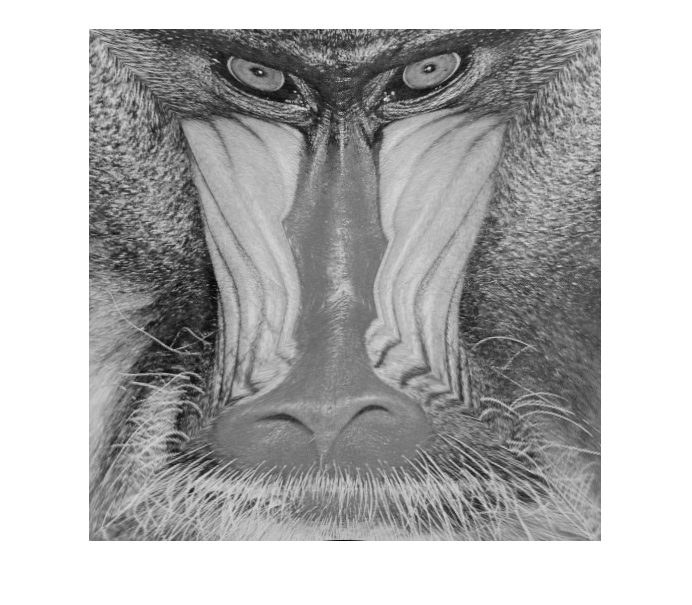


%diskBaboon = warp(barbara, inverseDisk(128.5));
%imshow(diskBaboon);

%resquaredBaboon = fromDisk(baboon);
%imshow(resquaredBaboon);

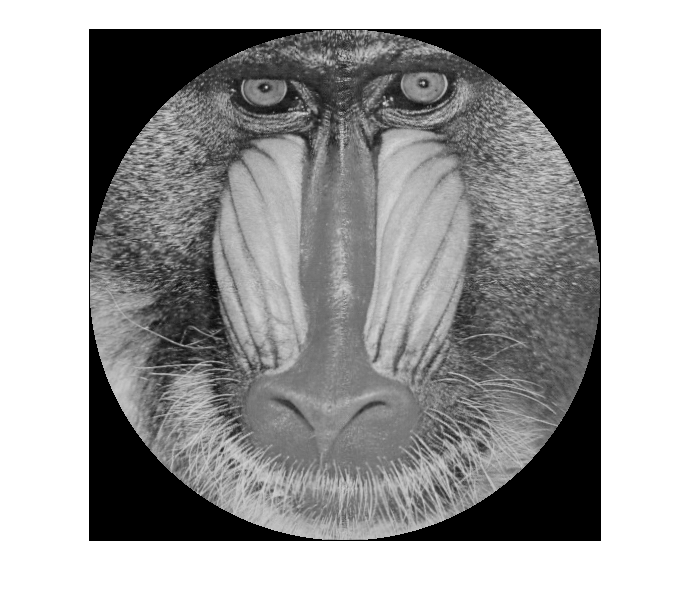

%imshow(toDisk(resquaredBaboon));

txClasses = zeros(64, 64, 15);
for i = 1:15
    txClasses(:, :, i) = readraw(srcDir + "sample" + string(i) + ".raw");
end

    "→Retrieving Image "    "..\srcImages\sample1.raw"    " ..."

    "→Retrieving Image "    "..\srcImages\sample2.raw"    " ..."

    "→Retrieving Image "    "..\srcImages\sample3.raw"    " ..."

    "→Retrieving Image "    "..\srcImages\sample4.raw"    " ..."

    "→Retrieving Image "    "..\srcImages\sample5.raw"    " ..."

    "→Retrieving Image "    "..\srcImages\sample6.raw"    " ..."

    "→Retrieving Image "    "..\srcImages\sample7.raw"    " ..."

    "→Retrieving Image "    "..\srcImages\sample8.raw"    " ..."

    "→Retrieving Image "    "..\srcImages\sample9.raw"    " ..."

    "→Retrieving Image "    "..\srcImages\sample10.raw"    " ..."

    "→Retrieving Image "    "..\srcImages\sample11.raw"    " ..."

    "→Retrieving Image "    "..\srcImages\sample12.raw"    " ..."

    "→Retrieving Image "    "..\srcImages\sample13.raw"    " ..."

    "→Retrieving Image "    "..\srcImages\sample14.raw"    " ..."

    "→Retrieving Image "    "..\srcImages\sample15.raw"    " ..."




classes = classifyLawsSmallTextures(txClasses, 5);

mosaic1 = readraw(srcDir + "comb1.raw");

    "→Retrieving Image "    "..\srcImages\comb1.raw"    " ..."



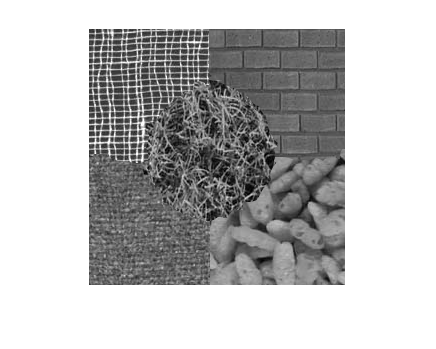

imshow(mosaic1);

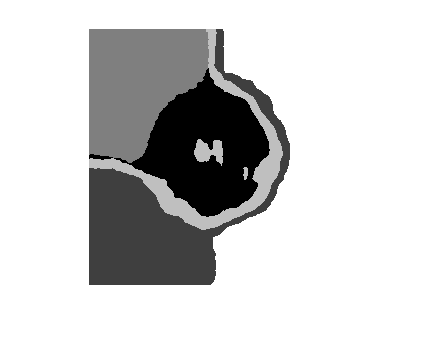

clustered = clusterTextures(mosaic1, [0, 63, 127, 191, 255]);
imshow(clustered);

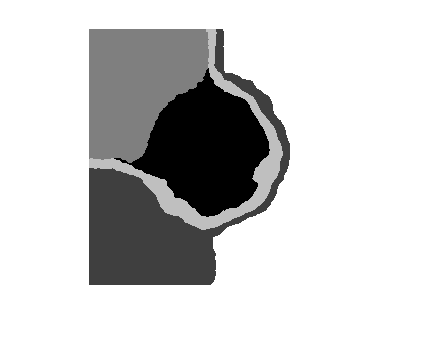

segmented = segmentClusters(clustered, [0, 63, 127, 191, 255]);
imshow(segmented);


mosaic2 = readraw(srcDir + "comb2.raw");

    "→Retrieving Image "    "..\srcImages\comb2.raw"    " ..."



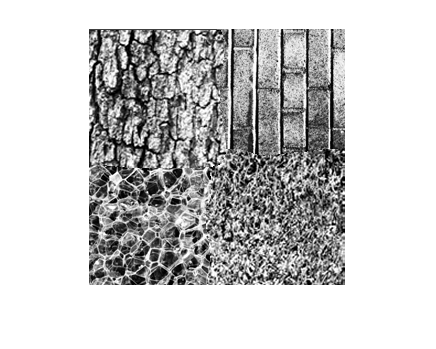

imshow(mosaic2);

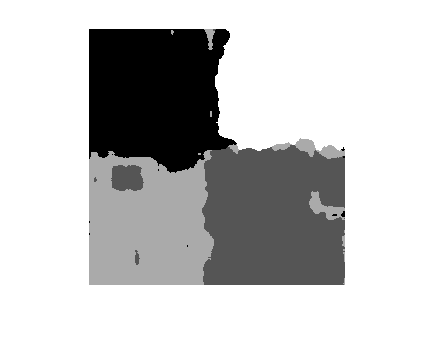

clustered = clusterTextures(mosaic2, [0, 85, 170, 255]);
imshow(clustered);

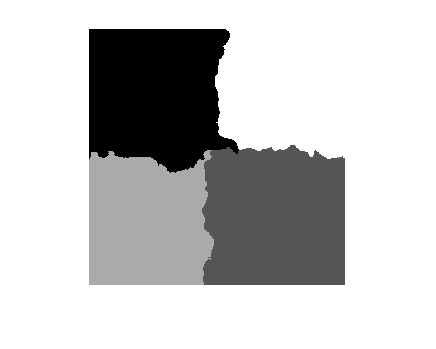

segmented = segmentClusters(clustered, [0, 85, 170, 255]);
imshow(segmented);

colors = [0, 85, 170, 255];
connectedParts = connectedComponents(segmented2);
frequencyList = frequencies(connectedParts);
keptComponents = largestComponents(segmented2, connectedParts, [0, 85, 170, 255], frequencyList);

keptComponents =     51    73     2     6


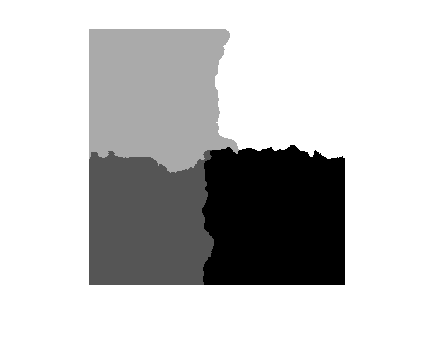

segmented = mergeComponents(connectedParts, frequencyList, keptComponents);
[rows, cols] = size(connectedParts);
for row = 1:rows
    for col = 1:cols
        for i = 1:4
            if segmented(row, col) == keptComponents(i)
                segmented(row, col) = colors(i);
            end
        end
    end
end
imshow(uint8(segmented));